# Modelowanie i symulacja w programie MATLAB cz.2

## Mateusz Wójcik, 17.10.2024

clear;
clc;
clf;

## Część III

W części III skupiono się na przetwarzaniu sygnału zapisanego w pliku o formacie *.csv. W trakcie zadania zostaną przeprowadzone takie operacje jak poglądowa analiza sygnału, wycinanie intersującej części z całego sygnalu, detrendowanie, czy wykreślanie widma FFT dla sygnału. W celu zdobycia umiejętności korzystania z tych funkcji, wykonano zlecone w konspekcie ćwiczenia:

**Zad a)**

importData.m:

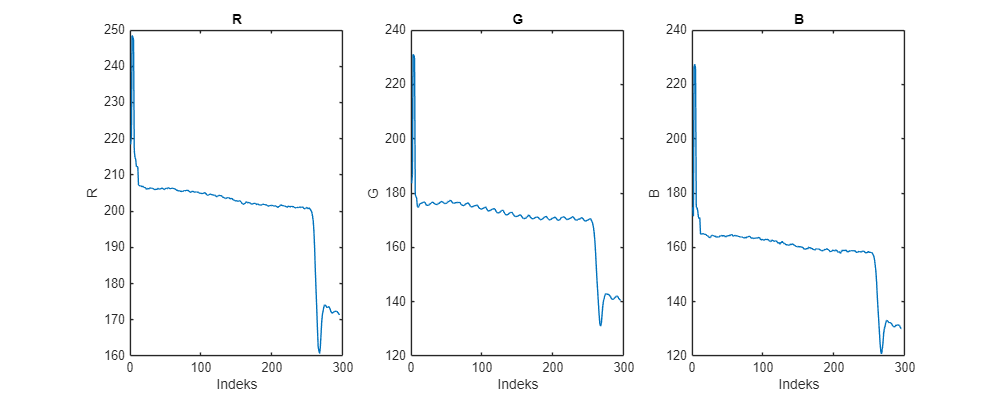

% Importowanie danych z pliku csv
% Skrypt importujący dane z pliku daneP.csv

filename = 'cwiczenia_A2_pliki/daneP.csv'; % Nazwa pliku
data = uiimport(filename); % Import danych

variables = data.colheaders;
numVariables = numel(variables);
% Tworzenie osobnych wykresów dla każdej zmiennej
clf;
figure;
set(gcf, "Position", [100 100 1000 400])
for i = 1:numVariables
    subplot(1, numVariables, i);
    plot(data.data(:, i)); % Rysowanie wykresu dla zmiennej i
    title(variables(i)); % Dodawanie tytułu opartego o nazwę zmiennej
    xlabel('Indeks'); % Etykieta osi x
    ylabel(variables(i)); % Etykieta osi y

end

Potwierdzenie działania skryptu:

importData;

**Zad b) i c)**

clf
hold on
x = 80:240;
sygnal_okres = data.data(x, 2);
plot(x,sygnal_okres)

Korzystając z narzędzia Basic Fitting Tool znaleziono, że funkcja liniowa dobrze przedstawia trend sygnału opisany funkcją:

$-0.0561 x + 180.117
$,

przy zachowaniu poziomu **norm of residuals = 2.93**

Wykres przedstawiono poniżej:

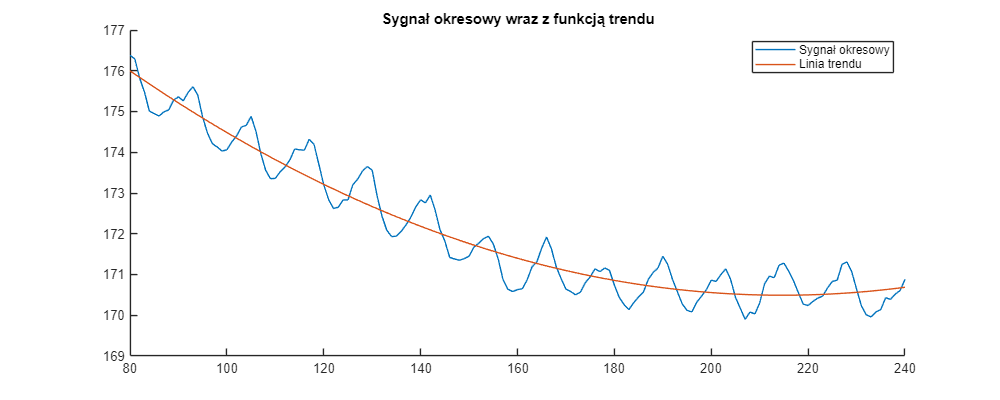

y = polyval(fit.coeff,x)';
plot(x, y)
title("Sygnał okresowy wraz z funkcją trendu")
legend(["Sygnał okresowy", "Linia trendu"])
hold off

**Usunięcie trendu z sygnału**

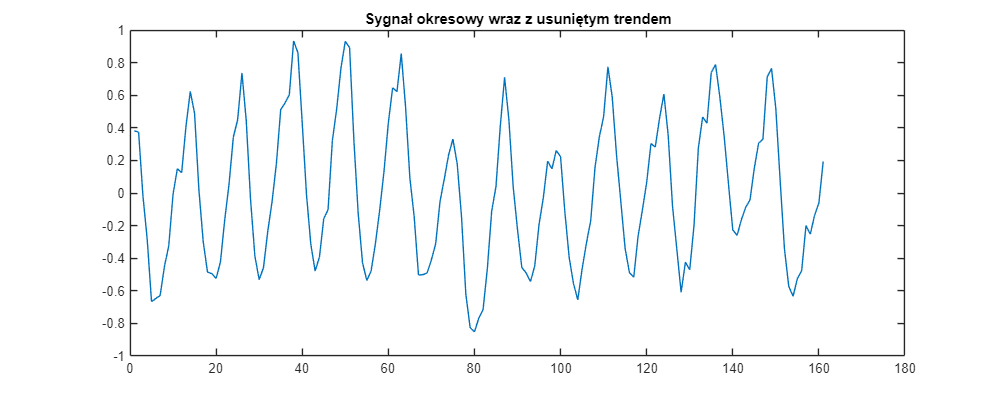

plot(sygnal_okres - y);
title("Sygnał okresowy wraz z usuniętym trendem")

**Zad d)**

Wyznaczenie FFT dla sygnału okresowego pozbawionego trendu:

Y = fft(sygnal_okres-y)

Y =   -0.0000 + 0.0000i
   3.3541 - 2.6820i
 -12.8000 + 5.8597i
  -0.4525 + 3.5968i
  -4.2910 - 1.3192i
  -1.1100 - 1.2306i
  -2.2290 - 6.9214i
   0.6351 + 4.2008i
  -2.1711 - 0.9342i
   1.6970 + 0.8177i


Narysowanie wykresu przedstawiającego FFT:

clf
fs = 60*15;
n = length(x);
f = 0:n/2;
f = f*fs/n;

hold on
plot(f, abs( 2*Y(1:floor(n/2)+1)/n))

title("FFT sygnału")
xlabel('Częstotliwość (Hz)');
ylabel('|Y(f)|');


Szukanie maksimum na wykresie i dodanie adnotacji na wykresie:

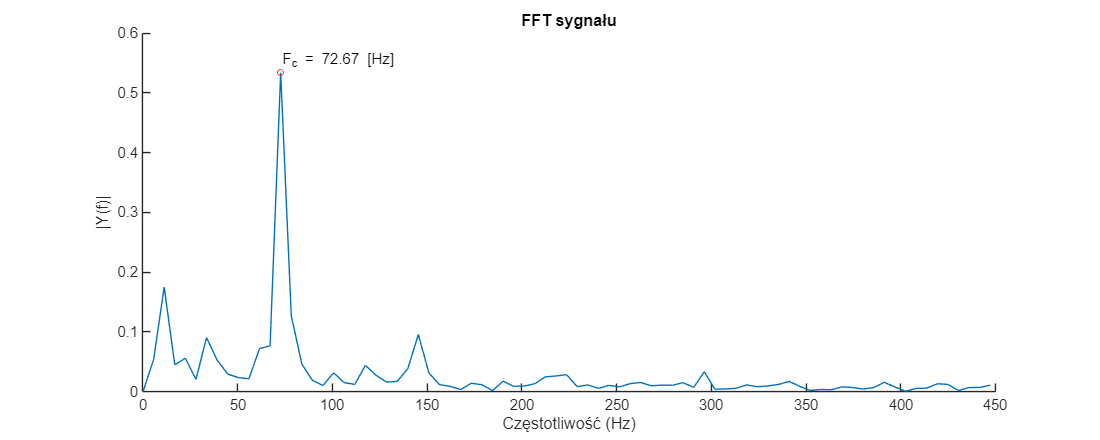

[val, idx] = max(abs( 2*Y(1:floor(n/2)+1)/n));
Fc = f(idx);
text_fc = sprintf("F_c = %.2f [Hz]",Fc);
text(Fc, val + 0.02, text_fc);
plot(Fc, val, "ro", MarkerSize=4)
hold off

## Część IV

Ćwiczenia w części czwartej zostały zaprojektowane pod rozwój ogólnych umiejętności korzystania z oprogramowania Matlab

**Zad a)**

clear
R = randn(3)

R =     1.0724   -0.6344    1.3769
    0.9680    0.6298   -1.4082
    0.2701   -0.0792    0.1412


A = uint32(100)

A = uint32
100

B = A  * uint32(R)

B = 3×3 uint32 matrix
   100     0   100
   100   100     0
     0     0     0


whos

  Name      Size            Bytes  Class     Attributes

  A         1x1                 4  uint32              
  B         3x3                36  uint32              
  R         3x3                72  double              



To ćwiczenie pokazuje, że do zapisania jednej liczby typu double potrzebne jest 8 bajtów, co jest równoważne 64 bitom. Jednocześnie dla typu uint32 potrzebna liczba bajtów wynosi tylko 8. Powyższe wyniki pokazują, że wraz z zmianą reprezentacji zapisu liczb w systemie cyfrowym możemy utracić znaczną część informacji na temat wcześniejszych danych.

**Zad b)**

tab1 = "ćwiczenie 2";
tab2 = "laboratorium 1";
str3 = strvcat(tab1, tab2)

str3 = 2×14 char array
    'ćwiczenie 2   '
    'laboratorium 1'


Zastosowano podstawową funkcję - **strvcat **umożliwiającą łączenie stringów w jedną tablicę.

**Zad c)**

str1 = "Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud";


Zdefiniowano wzorzec wyrażenia regularnego:

-  **\<b** oznacza, że słowo zaczyna się od litery "b"

- **\w*[^u]** oznacza dowolną liczbę znaków, ale bez litery "u"

-  **d\>** oznacza, że słowo kończy się na literę "d"

pattern = '\<b\w*[^u]d\>';

Użyto funkcji regexp do znalezienia indeksów spełniających wzorzec

indexes = regexp(str1, pattern);

Indeksy słów spełniających warunki:

disp(indexes);

    35    63



   Wyrażenia regularne pozwalają na szybką analizę tekstu oraz wydobowanie z niego kluczowych fragmentów tekstu, które nas aktualnie interesują. Często np. dla szukania adresów e-mail bądź nr telefonu itp.

**Zad d)**

tab ={123, "abcd";rand(3), 0.1}

tab = 2×2 cell array
    {[     123]}    {["abcd"]}
    {3×3 double}    {[0.1000]}


tab{2, 1} = tab{2, 1} + 100

tab = 2×2 cell array
    {[     123]}    {["abcd"]}
    {3×3 double}    {[0.1000]}


Przechowywanie w jednej strukturze pól o różnych polach pozwala na łatwiejszą organizację zmiennych, szczególnie dla bardziej skomplikowanych działań na liczbach.

**Zad e)**

f = @(x) x.^2 - 2*x +4

f = function_handle with value:
    @(x)x.^2-2*x+4


wartosc_calki = quad(f,-2,2)

wartosc_calki = 21.3333

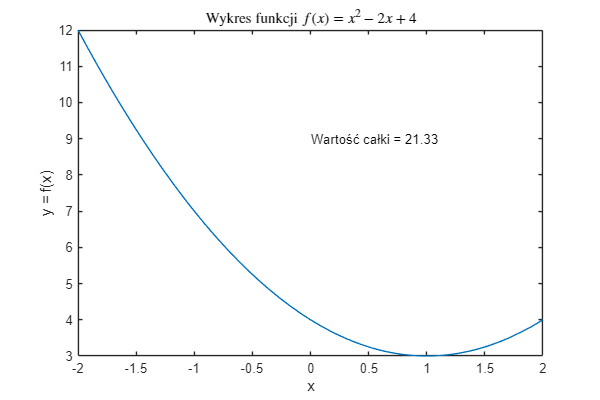

clf
set(gcf, "Position", [100 100 600 400])
fplot(f, [-2 2])
title("Wykres funkcji $f(x) = x^2 -2x + 4 $", Interpreter="latex")
ylabel('y = f(x)')
xlabel('x')
text(0,9, sprintf("Wartość całki = %.2f", wartosc_calki))

W środowisku Matlab istnieje możliwość tworzenia uchwytów do funkcji, które działają podobnie do wyrażeń lambda zdefiniowanych w innych językach programowania takich jak: C++, bądź Python. Dzięki temu można w łatwy sposób, bez zanieczyszczaniu Workspace, tworzyć funkcje oraz przekazywać im wartości liczbowe na danym przedziale. Dodatkowo korzystając z funkcji fplot otrzymano wykres wcześniej zdefiniowanego uchwytu do funkcji na zadanym parametrze.

**Zad f)**

col_names =  {'Matematyka','Fizyka','Chemia'};
row_names = {'Rafał', 'Monika', 'Paweł', 'Elżbieta', 'Mirek'};
col_num = length(col_names);
row_num = length(row_names);
result_f = table(round(100*rand(row_num, 1)), round(100*rand(row_num, 1)), round(100*rand(row_num, 1)),'VariableNames',col_names,'RowNames',row_names)

result_f = 5×3 table
                Matematyka    Fizyka    Chemia
                __________    ______    ______

    Rafał           27          94        19  
    Monika          24          82         0  
    Paweł           24          73        32  
    Elżbieta        15          18        70  
    Mirek           96          36        63  


writetable(result_f,'table_f.csv');

Możliwość tworzenia tabel oraz zapisywania ich w przystępnym dla użytkownika formacie pozwala na wyświetlanie danych w innych programach graficznych, lub dalszą obróbkę w innym środowisku. Kolejna struktura przechowywania danych pokazuje wszechstronność środowiska Matlab.

# Wnioski

Na zajęciach zapoznano się z podstawami analizy sygnału zarejestrowanego w zewnętrznym pliku. Mimo, że aktualnie nie zastosowano żadnego filtrowania sygnału, to nawet podstawowe operacje pozwalają na znaczną poprawę czytelności sygnału oraz zwiększenie ilości informacji, które możemy z niego wyciągnąć. W drugiej części ćwiczenia poznano kolejne funkcje środowiska Matlab. Złożonośc tego programu jest tak wielka, że każde ćwiczenie dotyczyło innego aspektu, który jest możliwy do wykonania w tym środowisku, a to wszystko to wierzchołek góry lodowej. Te wszystkie aspekty zachęcają do dalszego korzystania z Matlaba, i poznawania jego możliwości.